# Validation of the Models With Artificial Center-Surround Neuron

clear all
project_root_dir = '.';
addpath(genpath(fullfile(project_root_dir, 'src')));

### ============= Load Data =============

Import and recreate the sparse noise stimulus

config_file_path = 'Z:\LabMembers\Jong\Interneuron_multie\190417C\SN\processed\Cjsn5x4b2.m';
configs = Config(config_file_path);
sn_stim = SparseNoiseStimulus(configs.config);

Import the timestamps for when the stimulus happened

crs_file_path = 'Z:\LabMembers\Jong\Interneuron_multie\190417C\SN\processed\Cjsn5x4b2.ch4.crs';
stim_ts = StimTimeStamps(crs_file_path, configs.config);

WARNING!! deltimes between records in getcrs have variance >1%


### ====== Compute Design Matrix (Stimulus Mat) ======

% Creates design matrix with dimensions of:
% (receptive_temporal_length * gridsize^2), # of frames in stimulus
rf_temporal_len = 25; % frames
Xdsgn = make_design_matrix(sn_stim, rf_temporal_len);

### ========== Simulate Neuron With Given Stimulus ==========

% Create simulated spike data with the stimulus data
% Let's repeat the same stimulus 4 times just to increase the amount of
% data
repetition = 4;
[sim_spike, rf_spatial, rf_temporal] = simulate_neuron(repmat(Xdsgn,repetition,1), rf_temporal_len);

### ========== Visualize RF, STA, and Spike Trains ==========

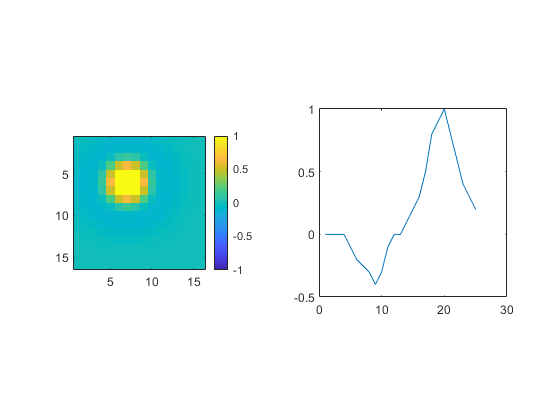

% Visualize the spatial and temporal receptive fields
figure;
subplot(1,2,1);
imagesc(rf_spatial, [-1,1]);
colorbar;
axis square;
subplot(1,2,2);
plot(1:rf_temporal_len,rf_temporal);
axis square;

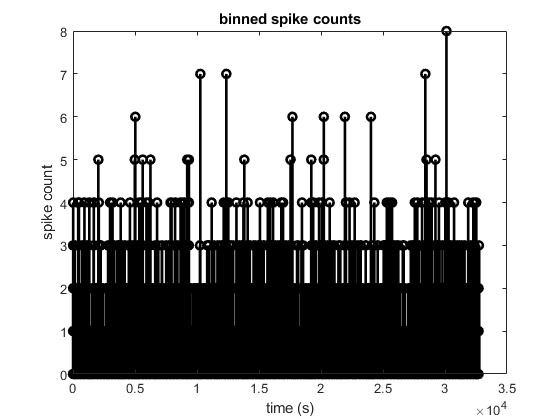

%Visualizing the simulated spikes in time
figure;
stem(sim_spike, 'k', 'linewidth', 2);
title('binned spike counts');
ylabel('spike count'); xlabel('time (s)');

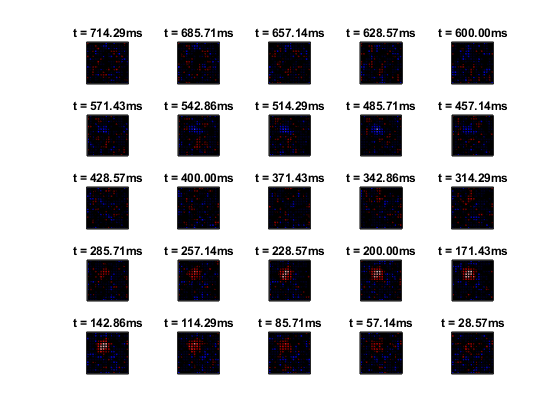

% Create Spike Triggered Average
sta = (repmat(Xdsgn,4,1)'*sim_spike)/(length(sim_spike));
sta = reshape(sta, [16,16,rf_temporal_len]);
figure;
plot_sta(sta, rf_temporal_len, 1/35);

### ========== Fit and Validate Methods ==========

### Method 1. GLMFit + temporal-spatial rf nonseparable - rf somewhat unclear

% Fit GLM
glm_sim = glmfit(repmat(Xdsgn,4,1), sim_spike, 'poisson','constant', 'on');

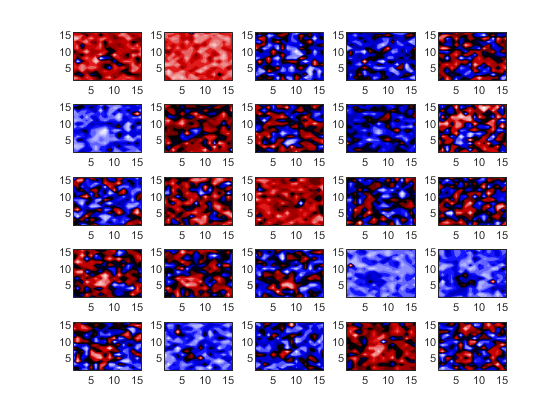

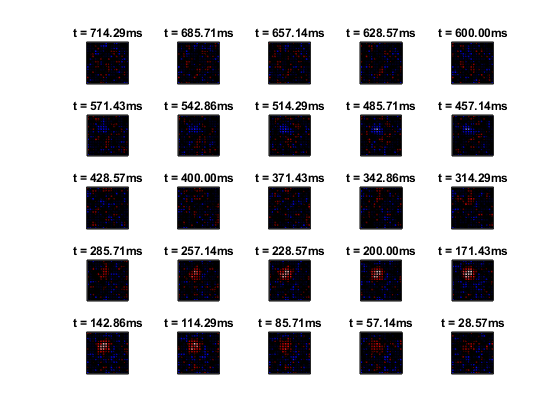

% Visualize the weights
sta_glm = reshape(glm_sim(2:end), [16,16,rf_t_len]);
plot_sta(sta_glm, rf_temporal_len, 1/35);

### **Method 2. GLMFit + temporal-spatial rf separable - good!**

defaultprs = {'Gradobj','on', 'maxiter', 1000, 'maxfunevals', 1e9, 'Display', 'iter'};
opts = optimset(defaultprs{:});
Loss = @(rf_weights) neg_log_likli_poisson(repmat(Xdsgn,4,1), sim_spike, rf_weights, 1/35, rf_temporal_len, 16);
init_weight = initialize_weight_from_sta(sta, 'separable');

[weight_final,neglogli,exitflag] = fminunc(Loss,init_weight,opts);

Neg Log Likelihood: 24992.860
gradient norm length: 1914.308
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          24992.9                           491
Neg Log Likelihood: 18958.412
gradient norm length: 1568.831
     1           2          18958.4     0.00203614            566  
Neg Log Likelihood: 76931849.539
gradient norm length: 391164651.748
Neg Log Likelihood: 67726.543
gradient norm length: 127057.439
Neg Log Likelihood: 19677.428
gradient norm length: 6850.074
Neg Log Likelihood: 18237.162
gradient norm length: 1643.683
     2           6          18237.2          0.125            471  
Neg Log Likelihood: 17571.454
gradient norm length: 6084.779
Neg Log Likelihood: 16810.542
gradient norm length: 2515.050
     3           8          16810.5        0.64295            463  
Neg Log Likelihood: 16534.891
gradient norm length: 5161.320
Neg Log Likelihood: 15612.589
grad

if (exitflag == 0)
    fprintf('max # evaluations or iterations exceeded (fminunc)\n');
end

% plot temporal and spatial rf
temporal_rf = weight_final(1:rf_temporal_len);
spatial_rf = reshape(weight_final(rf_temporal_len+1:end), 16,16);

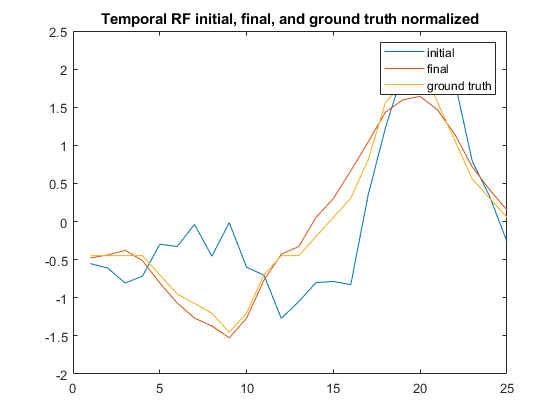

figure;
plot(normalize(init_weight(1:rf_temporal_len)));
hold on;
plot(normalize(temporal_rf));
plot(normalize(rf_temporal));
legend('initial', 'final', 'ground truth')
title('Temporal RF initial, final, and ground truth normalized')

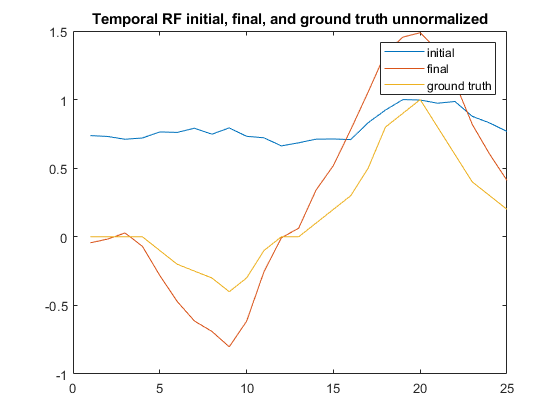

figure;
plot(init_weight(1:rf_temporal_len));
hold on;
plot(temporal_rf);
plot(rf_temporal);
legend('initial', 'final', 'ground truth')
title('Temporal RF initial, final, and ground truth unnormalized')

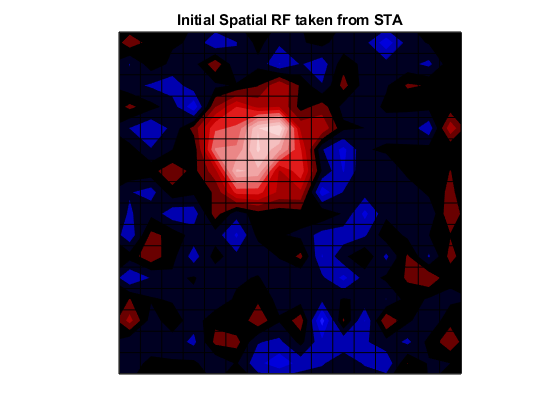

figure;
plot_sta(reshape(init_weight(rf_temporal_len+1:end),16,16), 1, 1);
title('Initial Spatial RF taken from STA')

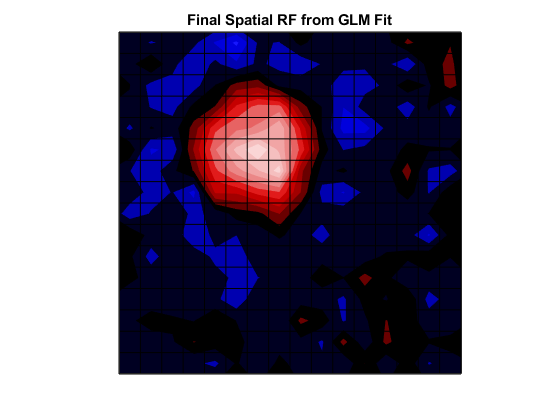

figure;
plot_sta(spatial_rf, 1, 1);
title('Final Spatial RF from GLM Fit')

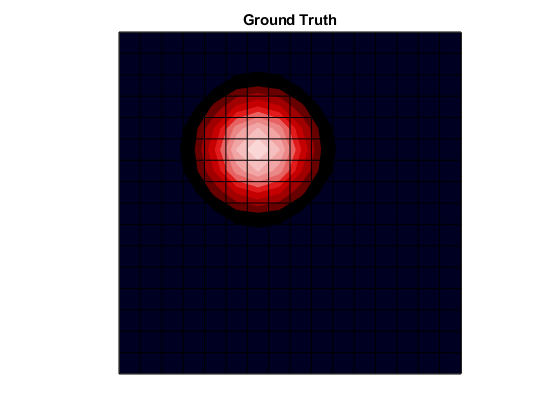

figure;
plot_sta(rf_spatial, 1,1)
title('Ground Truth')

### Method 3. GLMFit + temporal-spatial rf separable + temporal rf values constrained to -1~1 - much slower than method 2

lb = [repmat([-1],rf_temporal_len, 1);repmat([-Inf], 16^2,1)];
ub = [repmat([1],rf_temporal_len, 1);repmat([Inf], 16^2,1)];
[weight_temp_con,neglogli,exitflag] = fmincon(Loss,init_weight,[],[],[],[],lb,ub,[],opts);

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

Neg Log Likelihood: 24994.945
gradient norm length: 1737.783
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.499495e+04    0.000e+00    4.213e+02
Neg Log Likelihood: NaN
gradient norm length: NaN
Neg Log Likelihood: NaN
gradient norm length: NaN
Neg Log Likelihood: 2129377408819927998956158144491393737924022923140369371045077531275145778420888134480803348226895150978285724405571643812178597661048506473714908492384672914210671112170156819742720.000
gradient norm length: 368472545444621896078741722277968962070675587295702703491998808114357693707083166008057477552340498046404845789760126368363412962655806856184620561709596717330644129350854908990980096.000
Neg Log Likelihood: 1241220036111996504802165519916210077207223571918040015296696240870153821487276673254555648.000
gradie

if (exitflag == 0)
    fprintf('max # evaluations or iterations exceeded (fminunc)\n');
end

% plot temporal and spatial rf
temporal_rf_con = weight_temp_con(1:rf_temporal_len);
spatial_rf_con = reshape(weight_temp_con(rf_temporal_len+1:end), 16,16);

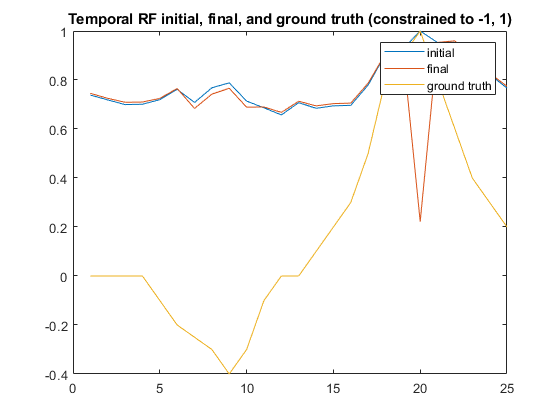

figure;
plot(init_weight(1:rf_temporal_len));
hold on;
plot(temporal_rf_con);
plot(rf_temporal);
legend('initial', 'final', 'ground truth')
title('Temporal RF initial, final, and ground truth (constrained to -1, 1)')

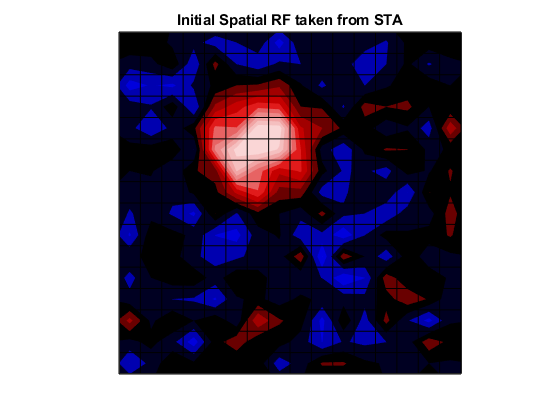

figure;
plot_sta(reshape(init_weight(rf_temporal_len+1:end),16,16), 1, 1);
title('Initial Spatial RF taken from STA')

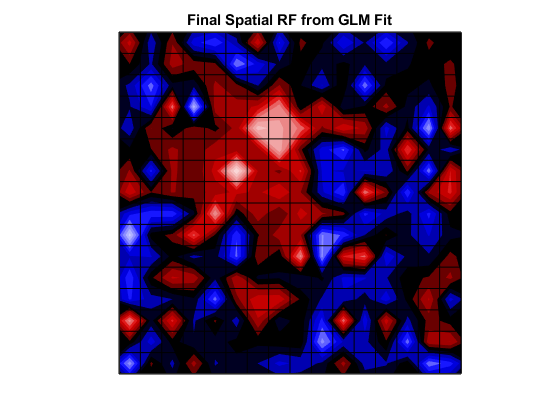

figure;
plot_sta(spatial_rf_con, 1, 1);
title('Final Spatial RF from GLM Fit')

figure;
plot_sta(rf_spatial, 1,1)
title('Ground Truth')

No visible improvement on spatial rf, but bad fitting on temporal rf!

### Method 3 + symbolic: Use symbolic function to auto-generate hessian / loss functions - too slow

sym_create_lossfn(rf_temporal_len, configs.config.gridsize, true, repmat(Xdsgn,4,1),sim_spike,1/35,[pwd filesep 'src'])
options = optimoptions(@fminunc,'Algorithm','interior-point','SpecifyObjectiveGradient',true,...
    'SpecifyConstraintGradient',true,'HessianFcn',@hess_likeli_sym,'Display','iter', 'maxiter', 1000);

### **Method 4. GLMFit + temporal-spatial rf separable + on-off separable**

defaultprs = {'Gradobj','on', 'maxiter', 1000, 'maxfunevals', 1e9, 'Display', 'iter'};
opts = optimset(defaultprs{:});
Loss = @(rf_weights) neg_log_likli_poisson(repmat(Xdsgn,4,1), sim_spike, rf_weights, 1/35, rf_temporal_len, 16);
init_weight = initialize_weight_from_sta(sta, 'separable');
spatial_rf_on = init_weight(rf_temporal_len+1:end);
spatial_rf_off = spatial_rf_on;
spatial_rf_on(spatial_rf_on<0)=0;
spatial_rf_off(spatial_rf_off>0)=0;
init_weight_onoff = [init_weight(1:rf_temporal_len); spatial_rf_on; spatial_rf_off];

[loss, dL] = neg_log_likli_poisson(repmat(Xdsgn,4,1), sim_spike, init_weight_onoff, 1/35, rf_temporal_len, 16);

Neg Log Likelihood: 24249.183
gradient norm length: 4810.805


[weight_final,neglogli,exitflag] = fminunc(Loss,init_weight_onoff,opts);

Neg Log Likelihood: 24249.183
gradient norm length: 4810.805
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1          24249.2                           619
Neg Log Likelihood: 804578.506
gradient norm length: 1664579.565
Neg Log Likelihood: 27478.660
gradient norm length: 24528.223
Neg Log Likelihood: 17288.490
gradient norm length: 1850.373
     1           4          17288.5    0.000403569            422  
Neg Log Likelihood: 20144.293
gradient norm length: 12228.248
Neg Log Likelihood: 16772.126
gradient norm length: 1648.679
     2           6          16772.1       0.383168            247  
Neg Log Likelihood: 15945.014
gradient norm length: 1219.076
     3           7            15945              1            154  
Neg Log Likelihood: 14924.545
gradient norm length: 2023.357
     4           8          14924.5              1            355  
Neg Log Likelihood: 14236.168
g

if (exitflag == 0)
    fprintf('max # evaluations or iterations exceeded (fminunc)\n');
end

% plot temporal and spatial rf
temporal_rf_onoff = weight_final(1:rf_temporal_len);
spatial_rf_on = reshape(weight_final(rf_temporal_len+1:rf_temporal_len+16^2), 16,16);
spatial_rf_off = reshape(weight_final(rf_temporal_len+16^2+1:end), 16,16);

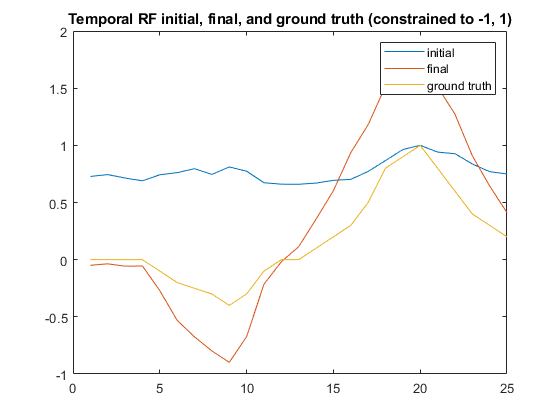

figure;
plot(init_weight_onoff(1:rf_temporal_len));
hold on;
plot(temporal_rf_onoff);
plot(rf_temporal);
legend('initial', 'final', 'ground truth')
title('Temporal RF initial, final, and ground truth (constrained to -1, 1)')

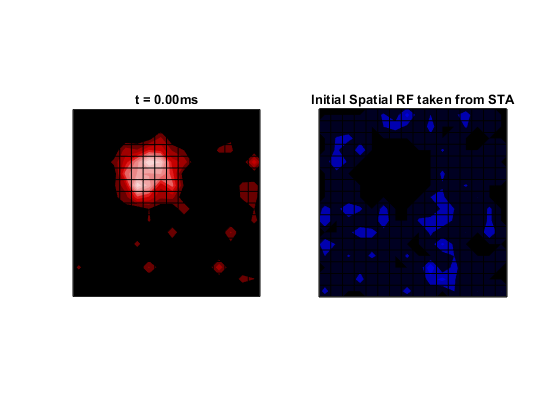

figure;
plot_sta(reshape(init_weight_onoff(rf_temporal_len+1:end),16,16,2), 2, 0);
title('Initial Spatial RF taken from STA')

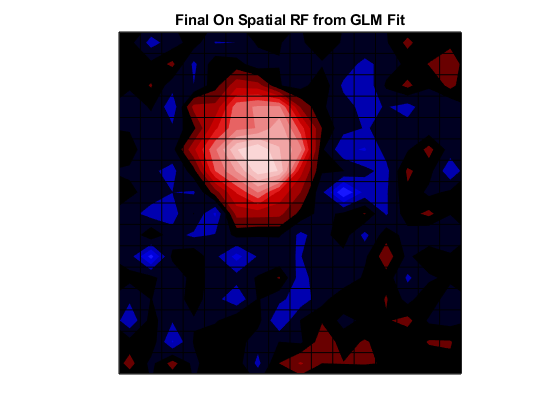

figure;
plot_sta(spatial_rf_on, 1, 0);
title('Final On Spatial RF from GLM Fit')

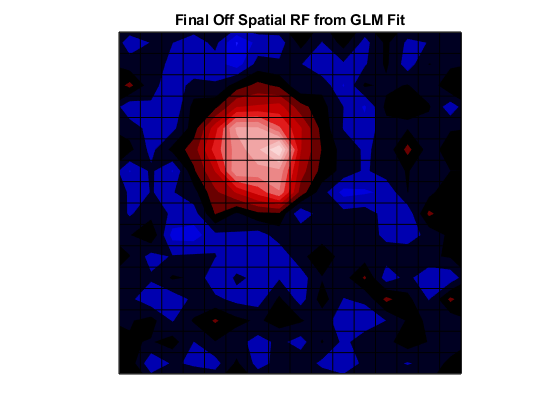

figure;
plot_sta(spatial_rf_off, 1, 0);
title('Final Off Spatial RF from GLM Fit')

### Method 4-1. GLMFit + temporal-spatial rf separable + on-off separable with on/off filters constrained to positive / negative respectively

defaultprs = {'fmincon','Gradobj','on', 'maxiter', 1000, 'maxfunevals', 1e9, 'Display', 'iter','Algorithm','trust-region-reflective','HessianFcn','objective'};
opts = optimoptions(defaultprs{:});
Loss = @(rf_weights) neg_log_likli_poisson(repmat(Xdsgn,4,1), sim_spike, rf_weights, 1/35, rf_temporal_len, 16);
init_weight = initialize_weight_from_sta(sta, 'separable');
spatial_rf_on = init_weight(rf_temporal_len+1:end);
spatial_rf_off = spatial_rf_on;
spatial_rf_on(spatial_rf_on<0)=0;
spatial_rf_off(spatial_rf_off>0)=0;
init_weight_onoff = [init_weight(1:rf_temporal_len); spatial_rf_on; spatial_rf_off];

[neglogli, dL, Hess] = neg_log_likli_poisson(Xdsgn, sim_spike(1:8192,1), init_weight_onoff, 1/35, rf_temporal_len, 16);

Neg Log Likelihood: 6447.627


lb = [repmat([-Inf],rf_temporal_len, 1);repmat([0], 16^2,1);repmat([-Inf],16^2,1)];
ub = [repmat([Inf],rf_temporal_len, 1);repmat([Inf], 16^2,1);repmat([0], 16^2,1)];
[weight_final,neglogli,exitflag] = fmincon(Loss,init_weight_onoff,[],[],[],[],lb,ub,[],opts);

Neg Log Likelihood: 24944.071


if (exitflag == 0)
    fprintf('max # evaluations or iterations exceeded (fminunc)\n');
end